close all; clc; clear all;

## Time span

tStart = 0;
tEnd = 100;
timeSpan = [tStart tEnd];

## Defining variables

global Kd Kp c v0 goal dMin

Kd = 1;
Kp = 1;
c = 1;
v0 = 0.2;
goal = [1;1];
dMin = 0.1;

## Initial conditions

initPhi = pi/4;
initPos = [-2;-2];
initR = 0;
z=[initPos;initPhi;initR];

## Solving ODE

[t,out] = ode45(@dinModel,timeSpan,z);

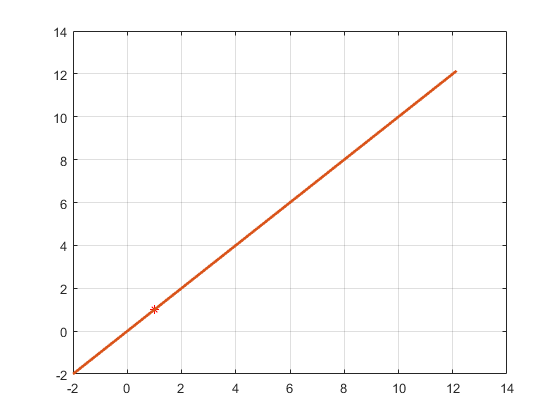

figure();
plot(goal(1),goal(2),"*r"), hold on;
plot(out(:,1),out(:,2),'LineWidth',2), grid;

%subplot(2,1,1);
% plot(t,out(:,6),t,out(:,7),t,out(:,5),'LineWidth',2),grid
% legend('$x(t)$','$y(t)$','$\phi(t)$',"Interpreter","latex",...
%         "Location","southeast");
% xlabel('t [s]',"Interpreter","latex")
% title("Pose of the DDMR in the dynamic model");
% 
% subplot(2,1,2);
% plot(t,out(:,1),t,out(:,2),'LineWidth',2),grid
% legend('$\phi_R(t)$','$\phi_L(t)$',"Interpreter","latex",...
%         "Location","southeast");
% xlabel('t [s]',"Interpreter","latex")
% title("Angular velocities of the DDMR wheels in the dynamic model");

## Functions

function zDot = dinModel(t,z)
    global Kd Kp c v0 goal dMin
        
    xDot = v0*cos(z(3));
    yDot = v0*sin(z(3));
    phiRef = atan((goal(2)-z(2))/(goal(1)-z(1)));
    e = phiRef - z(3);
    phiDot = -Kd*c^2*z(4)+(Kp+Kd*c)*e;
    phiR = -c*z(4)+e;
    
    d = sqrt((goal(2)-z(2))^2+(goal(1)-z(1))^2);
    
%     if(d < dMin)
%         v0 = 0;
%     end
%     
    zDot = [xDot;yDot;phiDot;phiR];
end